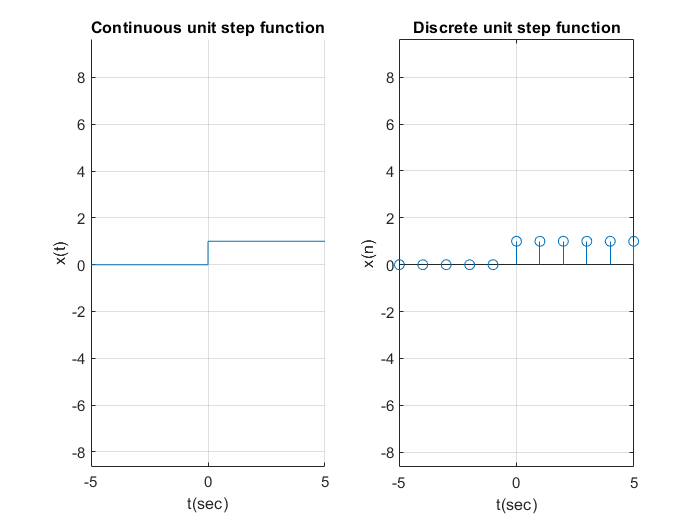

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-5:0.001:5;
x=t>=0;
figure;
subplot(1,2,1);
plot(t,x);xlabel('t(sec)');ylabel('x(t)'); %Continuous unit step function
title('Continuous unit step function');
grid on;
axis equal;
box off;
    
t=0:-1:-5;
t1=0:1:5;
fliplr(t);
t=horzcat(t,t1);
x=t>=0;
subplot(1,2,2);
stem(t,x);xlabel('t(sec)');ylabel('x(n)'); %Discrete unit step function
title('Discrete unit step function');
grid on;
axis equal;

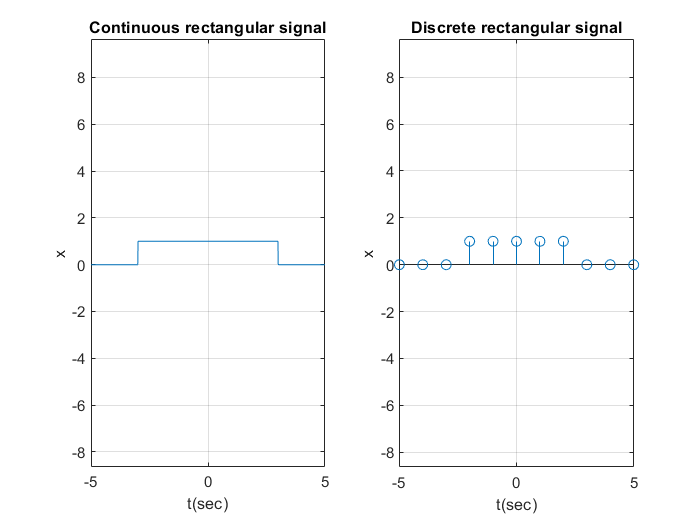

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-5:0.01:5;
x(t<3)=1;
x(t>=3)=0;
x(t<=-3)=0;

figure;
subplot(1,2,1);
plot(t,x);  %Continuous rectangular signal
title('Continuous rectangular signal');
xlabel('t(sec)');ylabel('x');
grid on;
axis equal;

t1=-5:5;
x1(t1<3)=1;
x1(t1>=3)=0;
x1(t1<=-3)=0;

subplot(1,2,2);
stem(t1,x1);    %Discrete rectangular signal
title('Discrete rectangular signal');
xlabel('t(sec)');ylabel('x');
grid on;
axis equal;

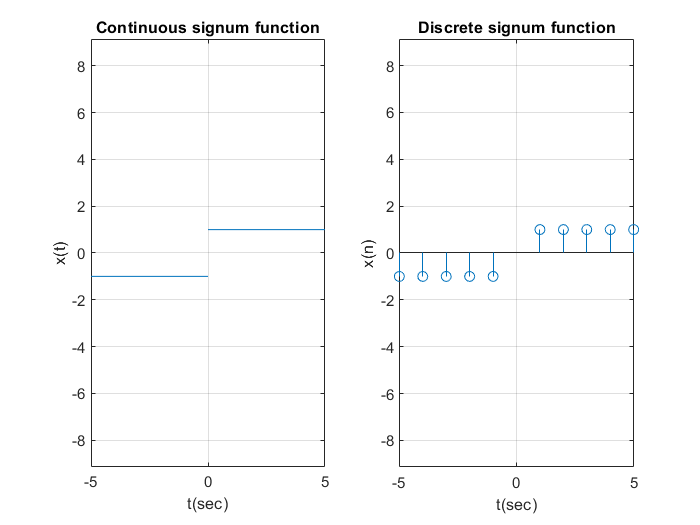

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------
t=-5:0.001:5;
x=t./abs(t);
figure;
subplot(1,2,1);
plot(t,x);  %Continuous signum function
title('Continuous signum function');
xlabel('t(sec)');ylabel('x(t)');
grid on;
axis equal;

t=-5:5;
x=t./abs(t);
subplot(1,2,2);
stem(t,x);  %Discrete signum function
title('Discrete signum function');
xlabel('t(sec)');ylabel('x(n)');
grid on;
axis equal;

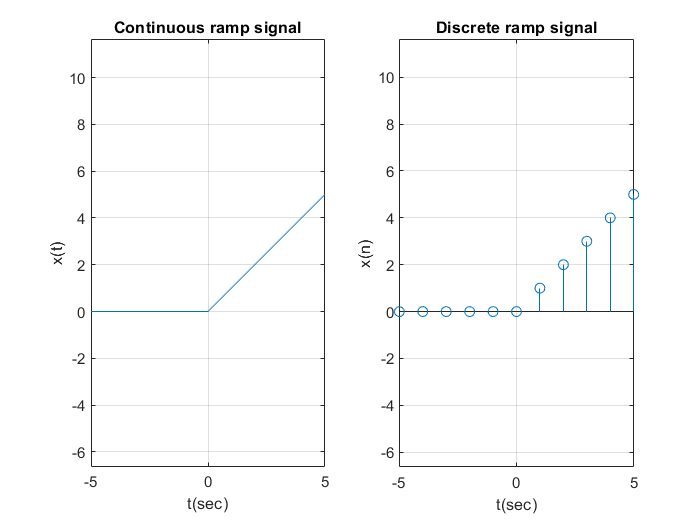

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-5:0.01:5;
x=(t>=0).*t;
figure;
subplot(1,2,1);
plot(t,x);  %Continuous ramp signal
grid on;
title('Continuous ramp signal');
xlabel('t(sec)');ylabel('x(t)');
axis equal;

t=-5:5;
x=(t>=0).*t;
subplot(1,2,2);
stem(t,x);  %Discrete ramp signal
grid on;
title('Discrete ramp signal');
xlabel('t(sec)');ylabel('x(n)');
axis equal;

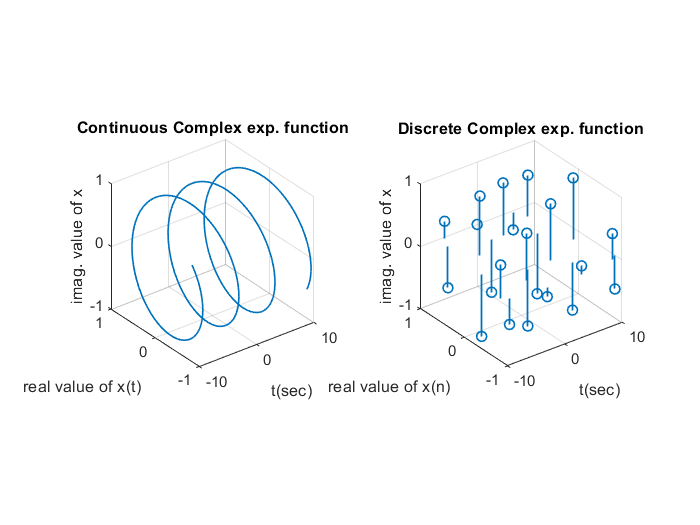

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-10:0.1:10;
x=exp(1i*t);

figure;
subplot(1,2,1);
plot3(t, real(x), imag(x), 'LineWidth',1);  %Continuous Complex exponential function
title('Continuous Complex exp. function');
xlabel('t(sec)');ylabel('real value of x(t)');zlabel('imag. value of x');
grid on;
axis square;

t1=-10:10;
x1=exp(1i*t1);
subplot(1,2,2);
stem3(t1, real(x1), imag(x1), 'LineWidth',1);   %Discrete Complex exponential function
title('Discrete Complex exp. function');
xlabel('t(sec)');ylabel('real value of x(n)');zlabel('imag. value of x');
grid on;
axis square;

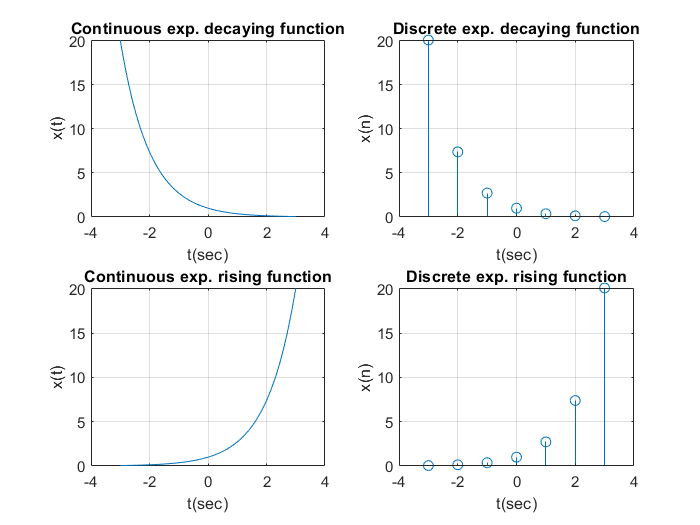

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-3:0.01:3;
x=exp(-t);  %Continuous exponential decaying function

figure;
subplot(2,2,1);
plot(t,x);
title('Continuous exp. decaying function');
xlabel('t(sec)');ylabel('x(t)');
grid on;

t1=-3:3;
x1=exp(-t1);    %Discrete exponential decaying function
subplot(2,2,2);
stem(t1,x1);
title('Discrete exp. decaying function');
xlabel('t(sec)');ylabel('x(n)');
grid on;

x=exp(t);
subplot(2,2,3);
plot(t,x);  %Continuous exponential rising function
title('Continuous exp. rising function');
xlabel('t(sec)');ylabel('x(t)');
grid on;

t1=-3:3;
x1=exp(t1);
subplot(2,2,4);
stem(t1,x1);    %Discrete exponential rising function
title('Discrete exp. rising function');
xlabel('t(sec)');ylabel('x(n)');
grid on;

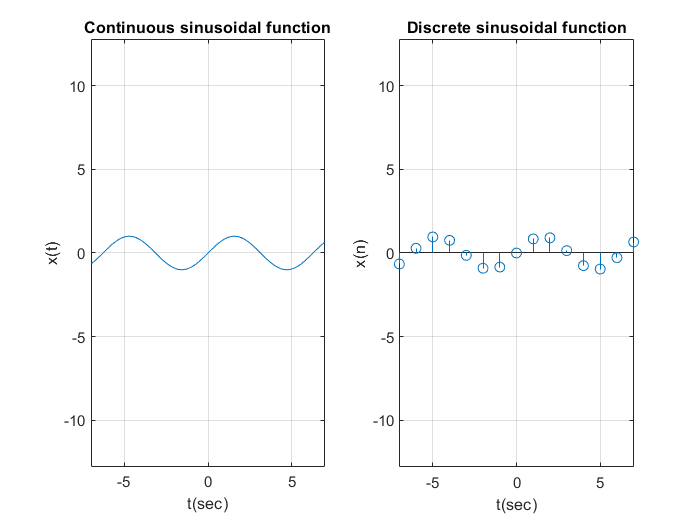

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-7:0.01:7;
x=sin(t);

figure;
subplot(1,2,1);
plot(t,x);  %Continuous sinusoidal function
title('Continuous sinusoidal function');
xlabel('t(sec)');ylabel('x(t)');
grid on;
axis equal;

t1=-7:7;
x1=sin(t1);
subplot(1,2,2);
stem(t1,x1);    %Discrete sinusoidal function
title('Discrete sinusoidal function');
xlabel('t(sec)');ylabel('x(n)');
grid on;
axis equal;

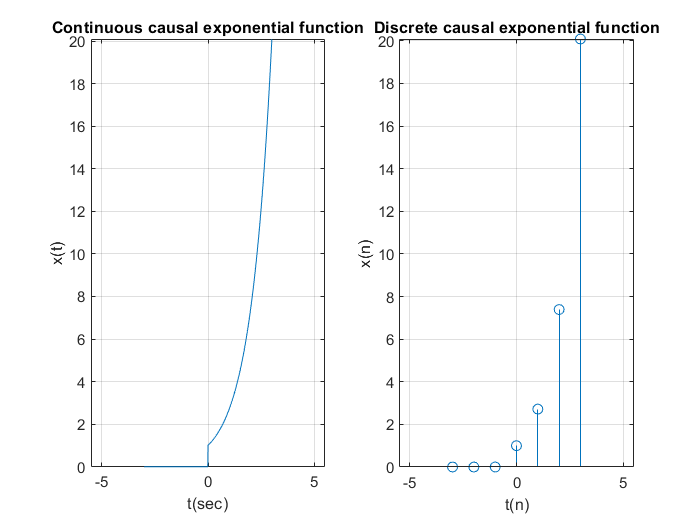

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------
t=-3:0.01:3;
x=(t>=0).*exp(t);

figure;
subplot(1,2,1);
plot(t,x);  %Continuous causal exponential function
title('Continuous causal exponential function');
xlabel('t(sec)');ylabel('x(t)');
grid on;
axis equal;

t1=-3:3;
x1=(t1>=0).*exp(t1);
subplot(1,2,2);
stem(t1,x1);    %Discrete causal exponential function
title('Discrete causal exponential function');
xlabel('t(n)');ylabel('x(n)');
grid on;
axis equal;

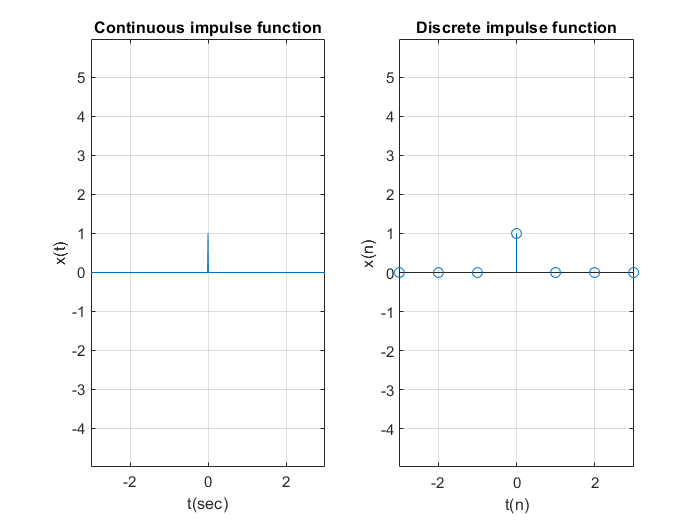

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-3:0.01:3;
x= (t==0);

figure;
subplot(1,2,1);
plot(t,x);  %Continuous impulse function
title('Continuous impulse function');
xlabel('t(sec)');ylabel('x(t)');
grid on;
axis equal;

t1=-3:3;
x1= (t1==0);
subplot(1,2,2);
stem(t1,x1);    %Discrete impulse function
title('Discrete impulse function');
xlabel('t(n)');ylabel('x(n)');
grid on;
axis equal;